## Edge Detection: Separating Overlapping Objects

Create a script that:

- Converts the image to grayscale

- Detects the edges of the grayscale image using the sobel method and saves the result as `imgEdges`. Specify your input options to skip the edge-thinning step to make your later segmentation more effective.

- Segments the grayscale image and saves the result as `BW`. Your mask should have the shapes in the foreground with a dark background

- Uses logical indexing or to remove the edges from the `BW` segmentation and saves the result as `newBW`. 

The original image, "DetectingEdgesSlide.png" is available in the course files. You are encouraged to work in MATLAB to inspect the images and choose thresholds that are appropriate for your segmentations. Your final segmentation should have 6 distinct regions instead of 5.

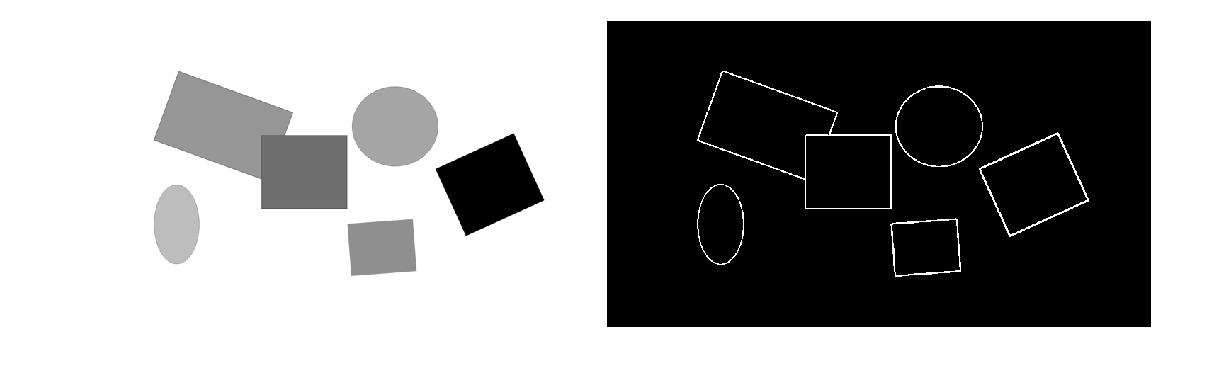

img = im2gray(imread("DetectingEdgesSlide.png"));
imgFilt = imgaussfilt(img, 1);
[imgEdges, threshOut, vertEdgeGrad, horzEdgeGrad] = edge(imgFilt, "sobel", "nothinning");
montage({img, imgEdges})

BW = imbinarize(img, 0.8);
Th = graythresh(img)

Th = 0.7137

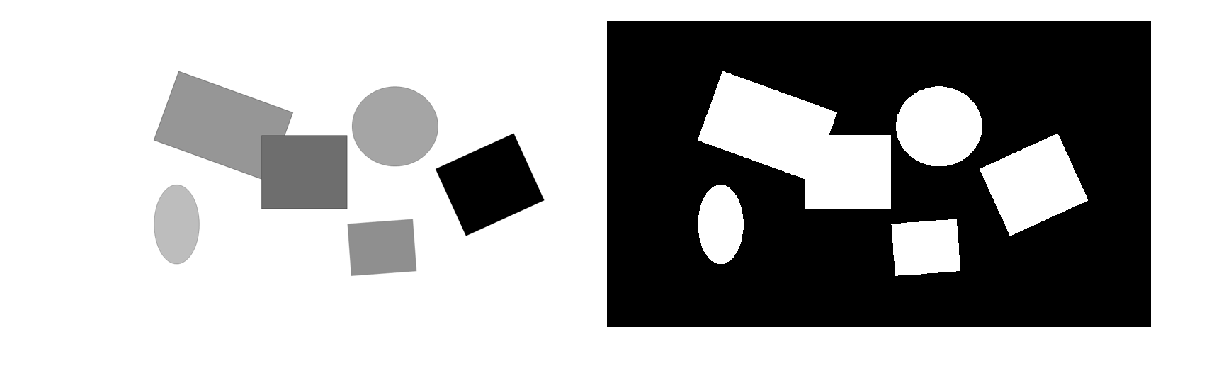

BW = ~BW;
montage({img, BW})

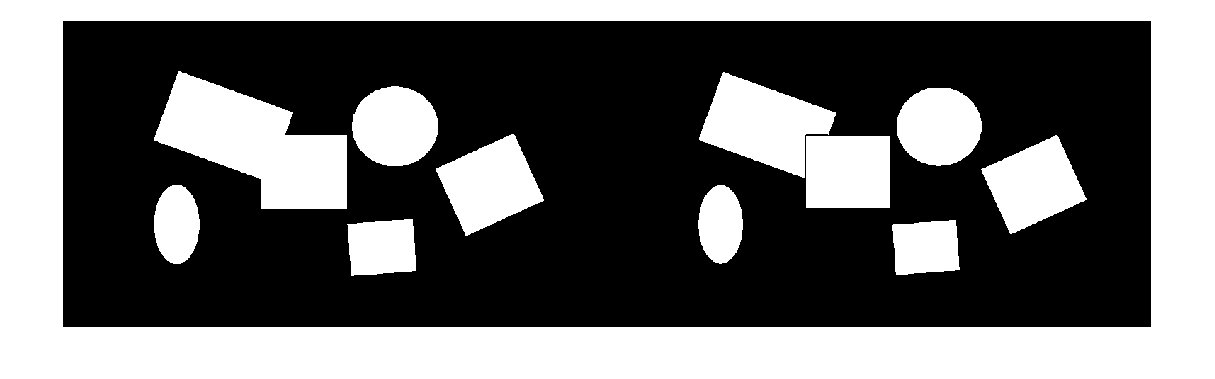

newBW = BW;
newBW(imgEdges) = 0;
montage({BW, newBW})

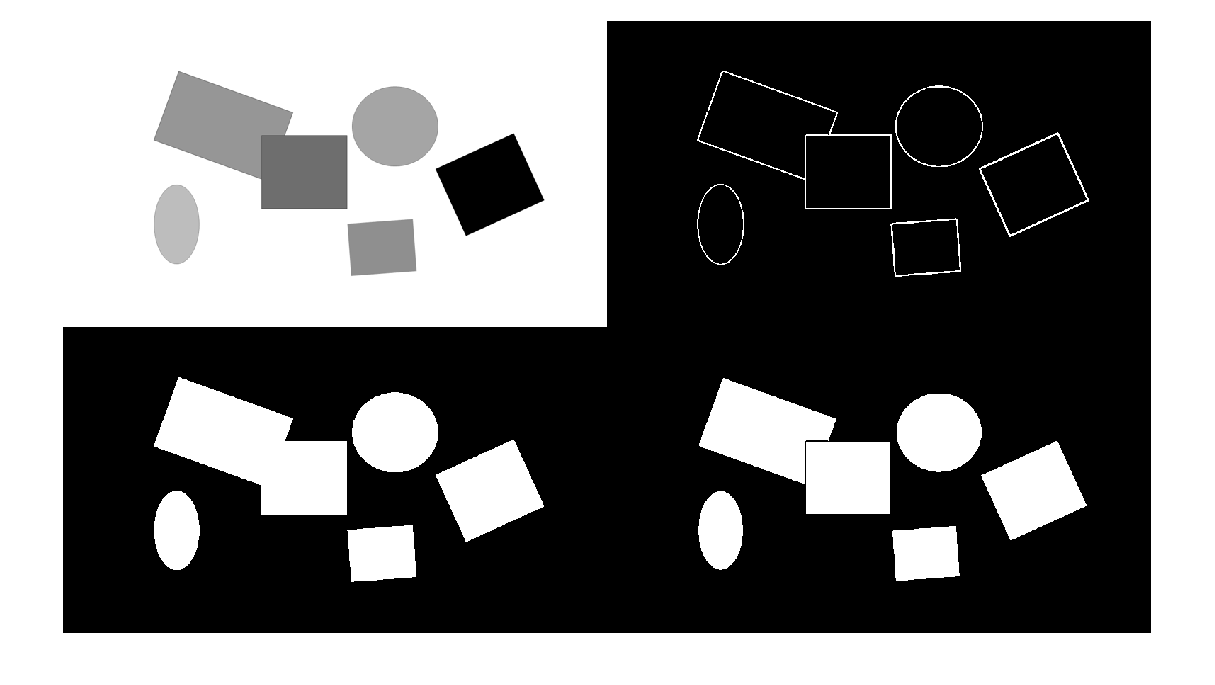

montage({img, imgEdges, BW, newBW})

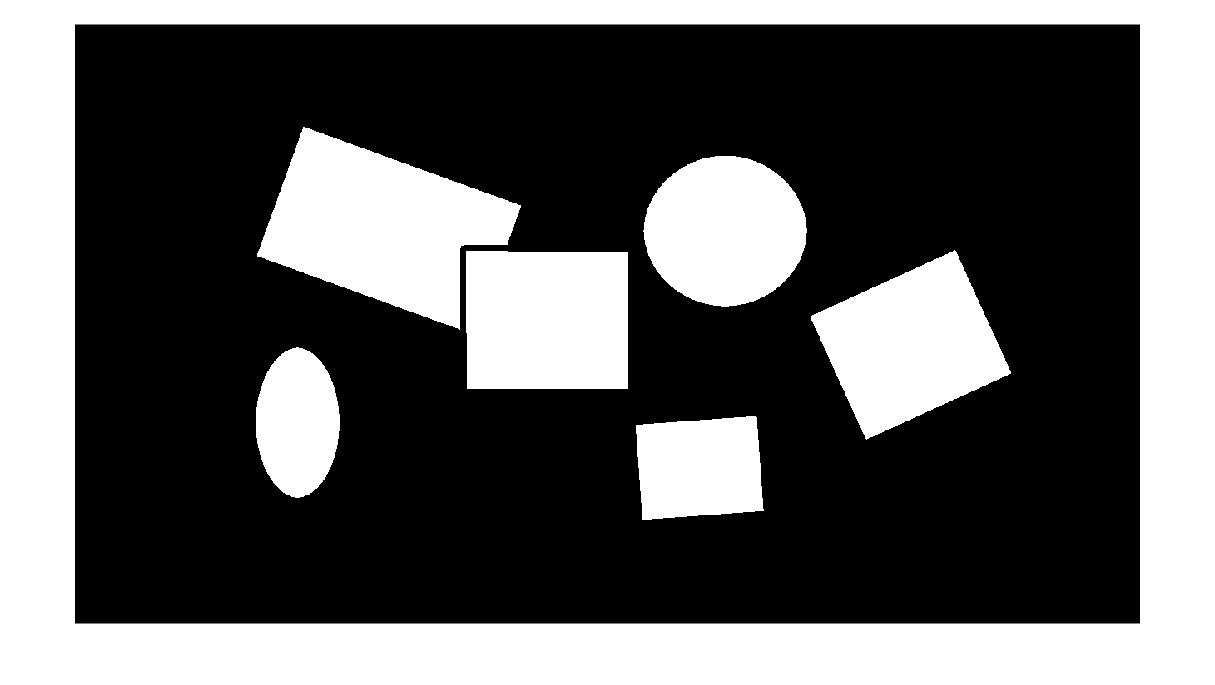

imshow(imerode(newBW,strel("disk",3)))